# WEEK 4 QUIZ 1

Question 1

Which of the following feature evaluation methods is appropriate for a continuous predictor and an ordinal categorical response. An ordinal categorical has an order to the categories, such as shirt sizes [S M L XL].

- Kendall correlation

- Pearson correlation

- The chi-square test

- ANOVA

disp("Kendall correlation , ANOVA")

Question 2

True or False: k-means clustering is an example of a **supervised **learning algorithm.

- True

- False

disp("False")

Question 3

True or False: The variance of a feature depends on its scale, so that a feature containing distances in kilometers will have a different variance if the distances are converted to meters.

- True

- False

disp("True")

Question 4

True or False: When engineering a new feature from an existing feature, the datatype of the new feature must match the datatype of the original features

- True

- False

disp("False")

Question 5

Given the silhouette plots below, what is the optimal number of clusters for the given dataset and clustering method?

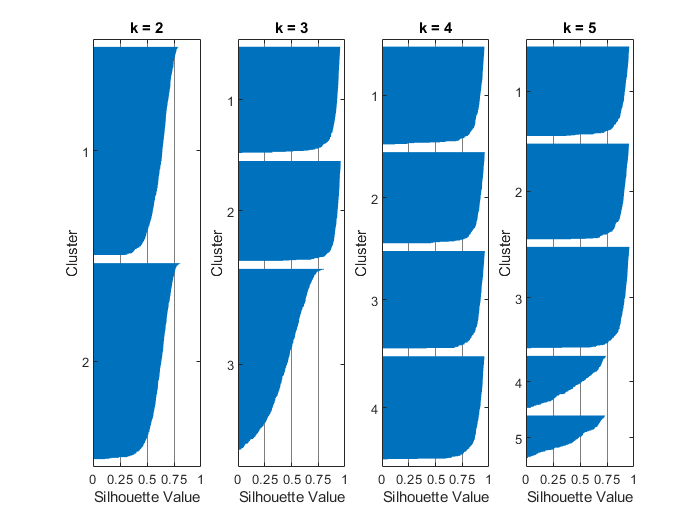

- 2

- 3

- 4

- 5

disp("4")

Question 6

Which type of correlation is appropriate for evaluating the strength of the relationship between *X* and *Y* as judged by the scatter plot below (select all that apply):

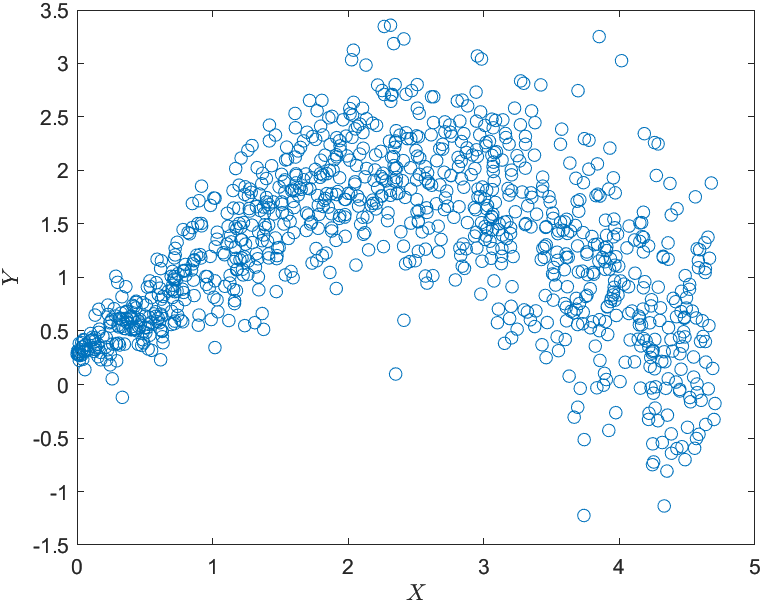

- Pearson

- Spearman

- Kendall

- Armstrong

- None

disp("None")

Question 7

The following questions use Fisher's iris dataset which contains measurements from 150 iris samples in a study. The dataset comes included with MALTAB. Load the matrix of measurements, named **meas**, and the corresponding species for each row by running the code:

`load fisheriris.mat meas species`

The data consists of measurements on the sepal length, sepal width, petal length, and petal width for 150 iris specimens. These measurement represent a set of 4 features which we denote X_1*X*1� ... X_4*X*4�.

Which feature has the largest variance?

- *X*1�

- *X*2�

- *X*3�

- *X*4

disp("X3")

Question 8

The features have different scales. Scale **meas** using the equation

measScaled = \frac{meas - mean(meas)}{max(meas) - min(meas)}*m**e**a**s**S**c**a**l**e**d*=*m**a**x*(*m**e**a**s*)−*m**i**n*(*m**e**a**s*)*m**e**a**s*−*m**e**a**n*(*m**e**a**s*)�

Which scaled feature as the highest variance? (remember to use './' for element-by-element division)

- *X*1�

- *X*2�

- *X*3�

- *X*4

disp("X4")

�

Question 9

Notice above that all four features in the scaled data are needed to explain 95% of the total variance.

Use the pca function on the*** scaled data***. How many principal component features (scores) are needed to capture 95% of the total variance? Remember that component variances are the 3rd output of the pca function. Refer to the reading "ApplyingPCA.mlx" in the Module 4 folder for information about the PCA function.

- 1

- 2

- 3

- 4

disp("2")

Question 10

Assume you want to use the principal component scores above (2nd output of pca, referred to as S in this quiz) to predict the cluster values. Use ANOVA to evaluate the scores as predictors. That is, use the anova1 function with each column of **S** and the variable **species** variable as the group. Which of the statements below is true?

- S_1*S*1� has the smallest p-value and the p-values increase for each principal component score.

- S_1*S*1� has the largest p-value and the p-values decrease for each principal component score.

- The p-values are related to the principal component scores, but the ordering of the principal component scores returned from the PCA function is random 

- The ordering of the p-values is not related to the ordering of principal component scores.

disp("S_1S1� has the smallest p-value and the p-values increase for each principal component score.")

Question 11

From the above analysis, you can reduce the number of features. For example:

`reducedData = ``S``(:, ``1``:``2``)`

where S is the principal component scores of the scaled data returned from the pca function.

Evaluate the optimal number of clusters using the evalclusters function and kmeans algorithm as shown below. 

`eva = evalclusters(reducedData,"kmeans", "``CalinskiHarabasz``", "``KList``", ``2``:``5``)`

There are four different options to use for the criterion (3rd input): 

- CalinskiHarabasz 

- DaviesBouldin

- gap

- silhouette

Which criterion(s) result in the optimal number of clusters being 3?  

- CalinskiHarabasz and silhouette

- silhouette and gap

- gap

- CalinskiHarabasz and gap

- None of the criterion return 3 as the optimal number of clusters  

- All  the criterion return 3 as the optimal number of clusters

disp("CalinskiHarabasz and gap")

Question 12

From the analysis in the previous question, you've learned that the optimal number of clusters is not always clear. Some species are very different while others are hard to distinguish.

Use the kmeans function to cluster the first two component features from the pca function (reducedData in the above question) using three clusters. Return two outputs from kmeans: The cluster assignments for each observation and the cluster centroids.

Which option below lists the three cluster centroids? The order may be different due to the randomness of starting centroid locations. 

As you're using only two features, you can visualize the results using a grouped scatter plot. Using syntax similar to below where the variable clst is the cluster assignment from the kmeans function and used as the grouping variable.

`% Clustered data  clst is the output from kmeans`

`gscatter(reducedData(:,``1``), reducedData(:,``2``), clst)`

- (-0.54, 0.12) , (-0.55, 0.09) , (0.11, -0.09)

- (0.61, 0.13) , (-0.68, 0.11) , (0.10, -0.16)

- (0.56, 0.10) , (-0.62, 0.07) , (0.15, -0.12)

- (0.45, 0.15) , (-0.6, 0.01) , (0.21, -0.08)

disp("(0.56, 0.10) , (-0.62, 0.07) , (0.15, -0.12)")